clear;
close all;

Set Parameter

img_org = "lena.jpeg";

获取图片信息

img_data = imread(img_org);
% 旋转图片
for P = 1:3
    img_org_data_uncut(:,:,P) = img_data(:,:,P)';
    img_org_data(:,:,P) = img_org_data_uncut(1:688,1:1032,P);
end
[h,w,p] = size(img_org_data);

`对二维灰度图像进行`DCT`变换，获得图像的频谱图`

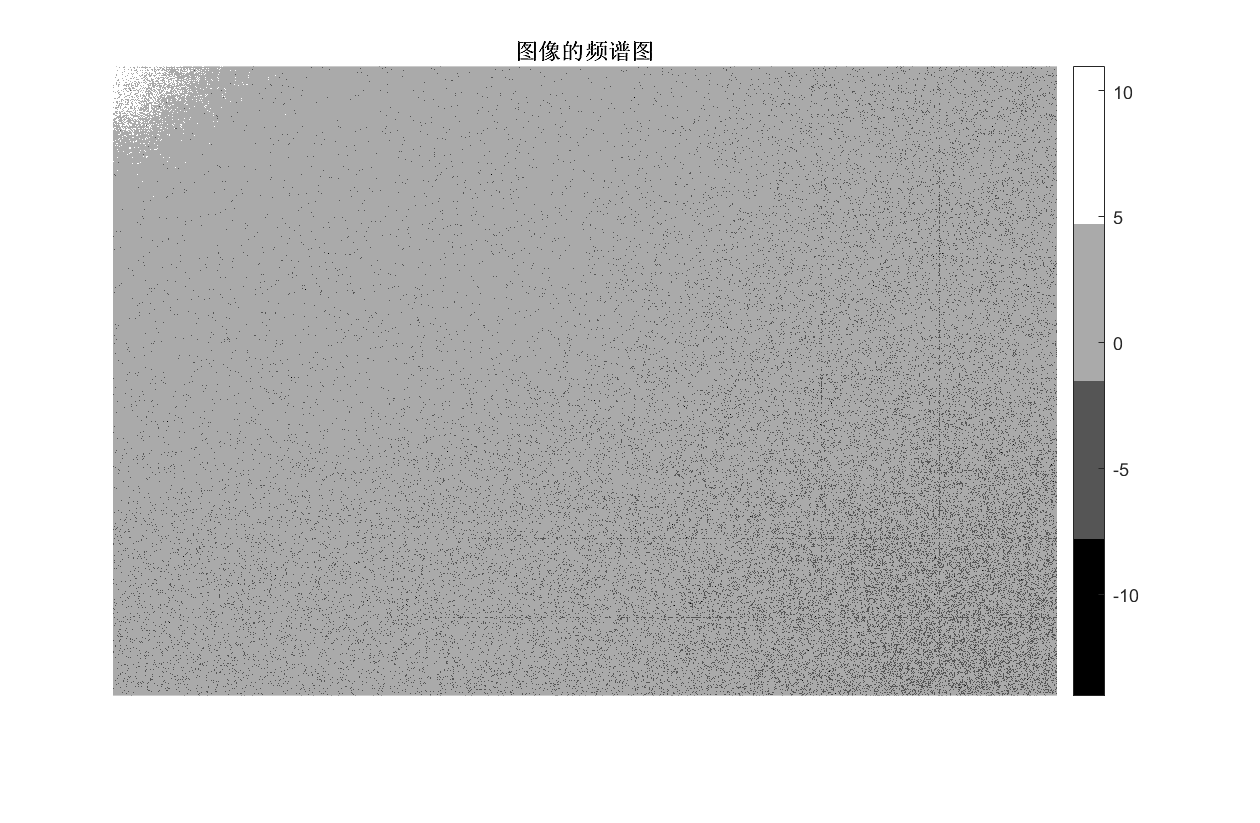

img_gray = rgb2gray(img_org_data);
img_gray_dct = dct2(img_gray);
figure(1);
set(gcf,'position',[0.2,0.2, 0.32,0.16]);
imshow(log(abs(img_gray_dct)),[]);
title('图像的频谱图');
colormap(gray(4));
colorbar;

8*8 DCT transform

% RGB图分层处理，得到3个分量图
R = img_org_data(:,:,1);
G = img_org_data(:,:,2);
B = img_org_data(:,:,3);

R_double = double(R);
G_double = double(G);
B_double = double(B);

% 建立8*8的DCT变换矩阵
T = dctmtx(8);

% Create DCT and IDCT function 
fundct = @(block_struct) T*block_struct.data*T';
funidct = @(block_struct) T'*block_struct.data*T;

% 进行DCT变换
R_DCT = blockproc(R_double,[8,8],fundct);
G_DCT = blockproc(G_double,[8,8],fundct);
B_DCT = blockproc(B_double,[8,8],fundct);

保留左上角前2条对角线上的系数

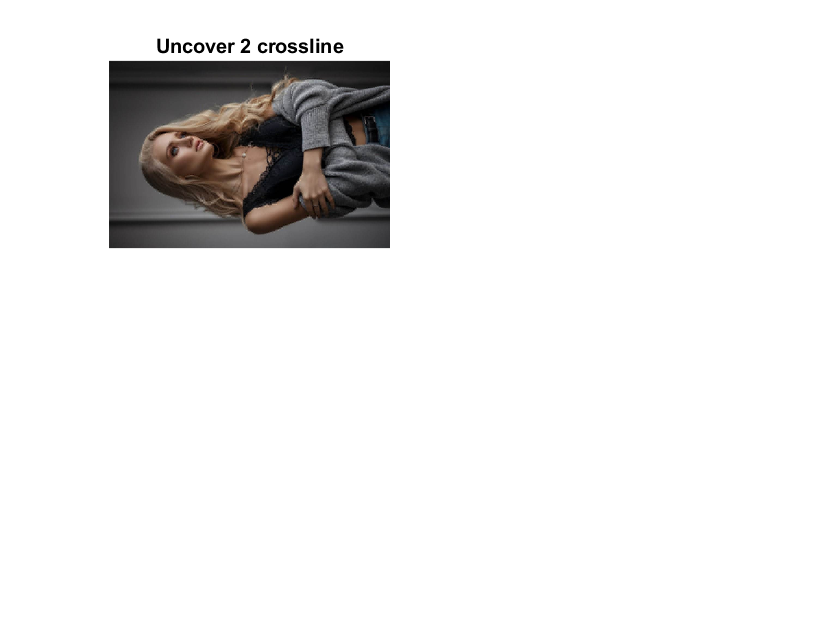

mask2 = ...
    [1 1 0 0 0 0 0 0
     1 0 0 0 0 0 0 0
     0 0 0 0 0 0 0 0
     0 0 0 0 0 0 0 0
     0 0 0 0 0 0 0 0
     0 0 0 0 0 0 0 0
     0 0 0 0 0 0 0 0
     0 0 0 0 0 0 0 0];
fun2 = @(block_struct) mask2.*block_struct.data;

% 对DCT系数进行遮罩处理
R_DCT_mask2 = blockproc(R_DCT,[8 8],fun2);
G_DCT_mask2 = blockproc(G_DCT,[8 8],fun2);
B_DCT_mask2 = blockproc(B_DCT,[8 8],fun2);

% IDCT
R_mask2 = blockproc(R_DCT_mask2,[8 8],funidct);
G_mask2 = blockproc(G_DCT_mask2,[8 8],funidct);
B_mask2 = blockproc(B_DCT_mask2,[8 8],funidct);

R_mask2 = uint8(R_mask2);
G_mask2 = uint8(G_mask2);
B_mask2 = uint8(B_mask2);

img_mask2 = img_org_data;
img_mask2(:,:,1) = R_mask2;
img_mask2(:,:,2) = G_mask2;
img_mask2(:,:,3) = B_mask2;

figure("Name",'Image after IDCT');
subplot(2,2,1);
imshow(img_mask2);
title("Uncover 2 crossline");

保留左上角前4条对角线上的系数

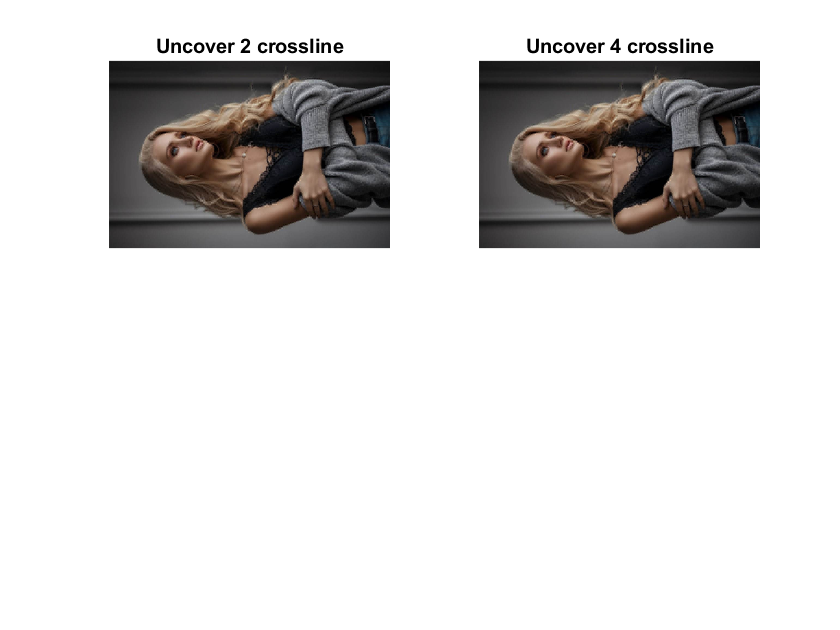

mask4 = ...
    [1 1 1 1 0 0 0 0
     1 1 1 0 0 0 0 0
     1 1 0 0 0 0 0 0
     1 0 0 0 0 0 0 0
     0 0 0 0 0 0 0 0
     0 0 0 0 0 0 0 0
     0 0 0 0 0 0 0 0
     0 0 0 0 0 0 0 0];
fun4 = @(block_struct) mask4.*block_struct.data;

% 对DCT系数进行遮罩处理
R_DCT_mask4 = blockproc(R_DCT,[8 8],fun4);
G_DCT_mask4 = blockproc(G_DCT,[8 8],fun4);
B_DCT_mask4 = blockproc(B_DCT,[8 8],fun4);

% IDCT
R_mask4 = blockproc(R_DCT_mask2,[8 8],funidct);
G_mask4 = blockproc(G_DCT_mask2,[8 8],funidct);
B_mask4 = blockproc(B_DCT_mask2,[8 8],funidct);

R_mask4 = uint8(R_mask4);
G_mask4 = uint8(G_mask4);
B_mask4 = uint8(B_mask4);

img_mask4 = img_org_data;
img_mask4(:,:,1) = R_mask4;
img_mask4(:,:,2) = G_mask4;
img_mask4(:,:,3) = B_mask4;

subplot(2,2,2);
imshow(img_mask4);
title("Uncover 4 crossline");

保留左上角前6条对角线上的系数

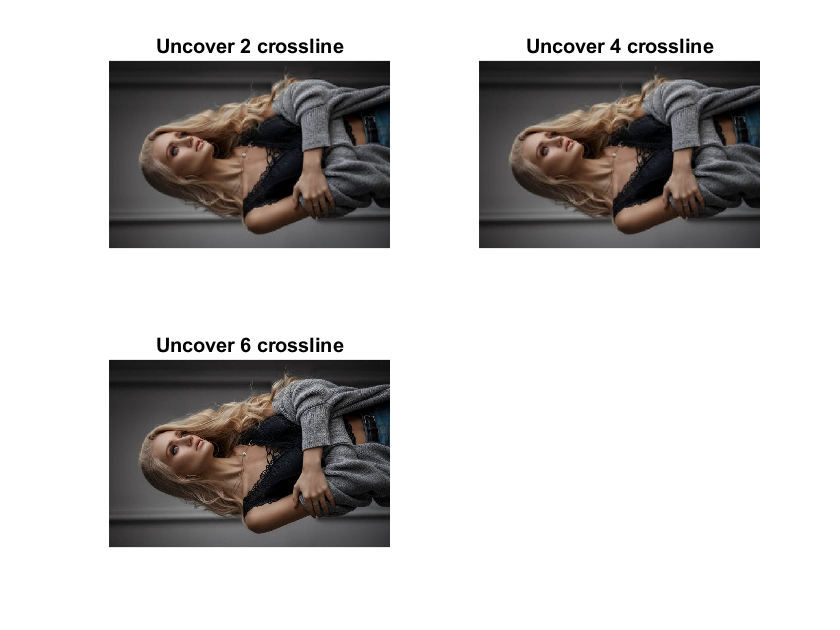

mask6 = ...
    [1 1 1 1 1 1 0 0
     1 1 1 1 1 0 0 0
     1 1 1 1 0 0 0 0
     1 1 1 0 0 0 0 0
     1 1 0 0 0 0 0 0
     1 0 0 0 0 0 0 0
     0 0 0 0 0 0 0 0
     0 0 0 0 0 0 0 0];
fun6 = @(block_struct) mask6.*block_struct.data;

% 对DCT系数进行遮罩处理
R_DCT_mask6 = blockproc(R_DCT,[8 8],fun6);
G_DCT_mask6 = blockproc(G_DCT,[8 8],fun6);
B_DCT_mask6 = blockproc(B_DCT,[8 8],fun6);

% IDCT
R_mask6 = blockproc(R_DCT_mask6,[8 8],funidct);
G_mask6 = blockproc(G_DCT_mask6,[8 8],funidct);
B_mask6 = blockproc(B_DCT_mask6,[8 8],funidct);

R_mask6 = uint8(R_mask6);
G_mask6 = uint8(G_mask6);
B_mask6 = uint8(B_mask6);

img_mask6 = img_org_data;
img_mask6(:,:,1) = R_mask6;
img_mask6(:,:,2) = G_mask6;
img_mask6(:,:,3) = B_mask6;

subplot(2,2,3);
imshow(img_mask6);
title("Uncover 6 crossline");

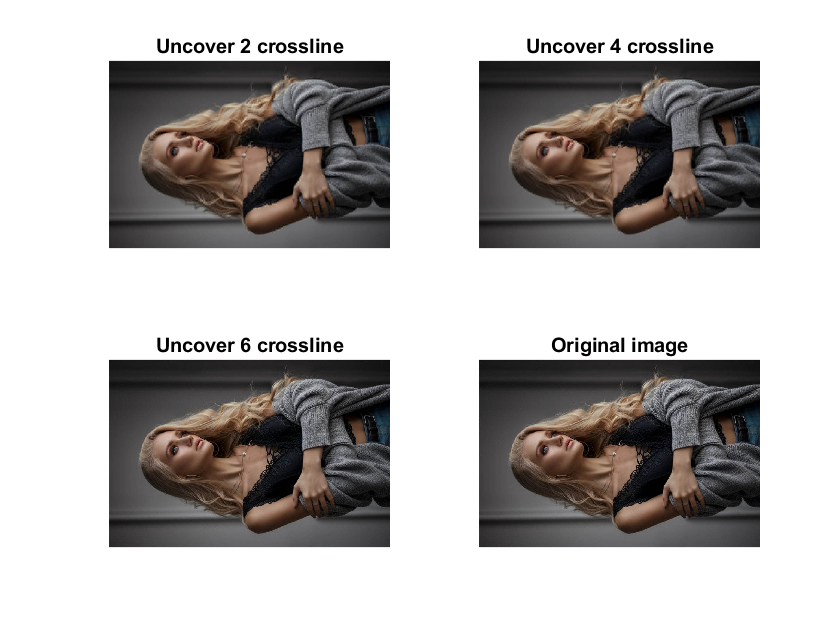

subplot(2,2,4);
imshow(img_org_data);
title("Original image");